**Sampling Mechanisms in MATLAB**

**Kuan-Min Lee**

**Downsampling functions:**

**Downsample ():**

**Def:**

decrease sample rate by integer factor

**Syntax:**

**downsample(x,n,phase)**

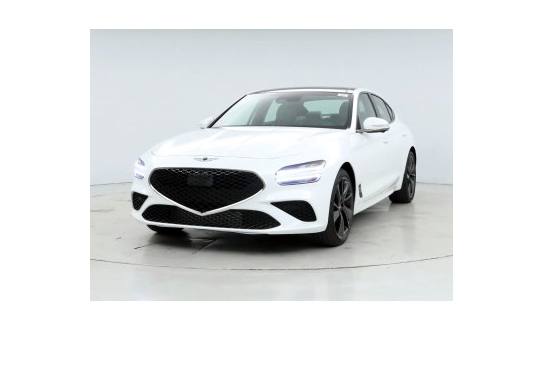

car_img=imread("car.jpg"); % read in sample image
figure(1);
imshow(car_img)

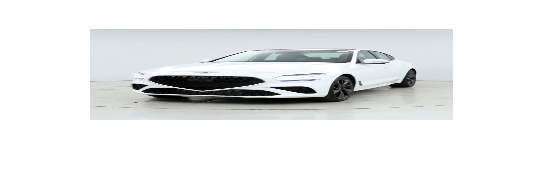

down_car_img=downsample(car_img,3);
figure(2);
imshow(down_car_img)

**Upsampling function:**

**Upsample():**

**Def:**

increase sample rate by integer factor

**Syntax:**

**upsample(x,n,phase)**

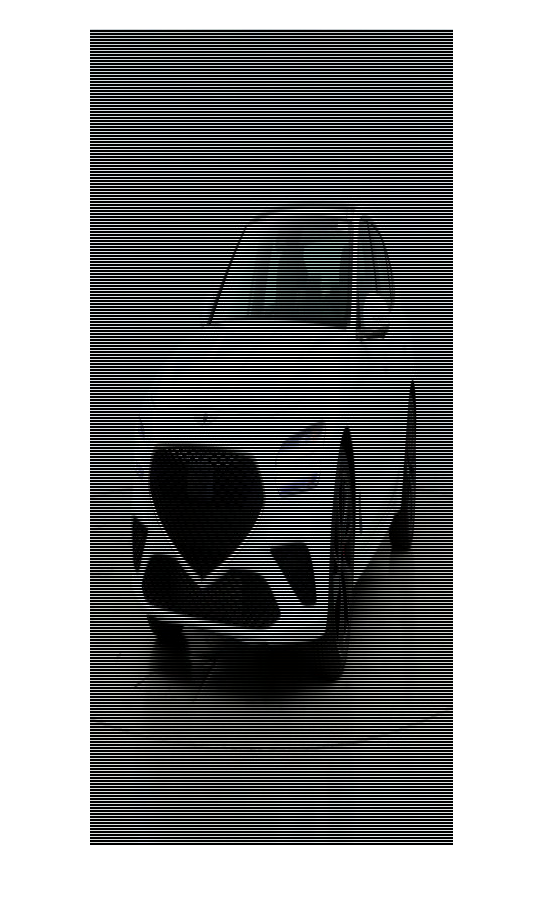

up_car_img=upsample(car_img,3);
figure(3);
imshow(up_car_img)

**interp():**

**Def:**

Increase the sample rate of x by a factor

**Syntax:**

**interp(x,r,n,cutoff)**

**n: half the number of original sample used to interpolate the signal**

**cutoff: normalized cutoff frequency**

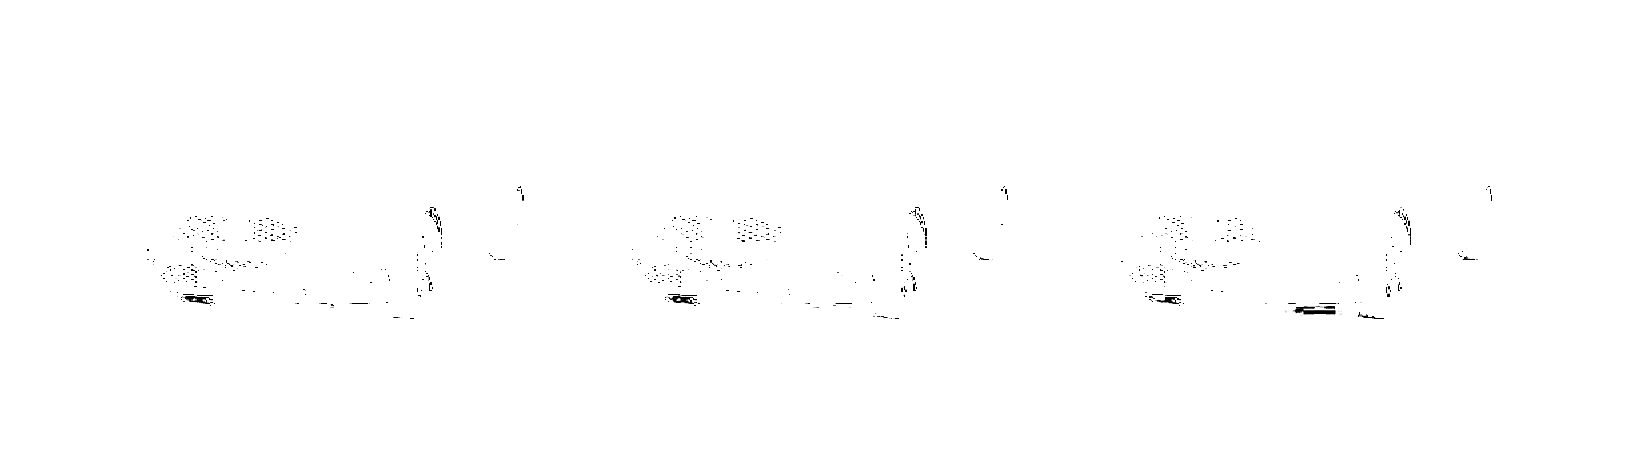

new_img_temp=[];
n_wid=size(car_img,1);
for i_wid=1:n_wid
    % extract each row of the image
    curr_img=car_img(i_wid,:);
    new_curr_img=interp(double(curr_img),4);
    new_img_temp=[new_img_temp; new_curr_img];
end
new_img=[];
n_col=size(new_img_temp,2);
for i_col=1:n_col
    % extract each column of the image
    curr_img=new_img_temp(:,i_col);
    new_curr_img=interp(double(curr_img),4);
    new_img=[new_img new_curr_img];
end
figure(4);
imshow(new_img)

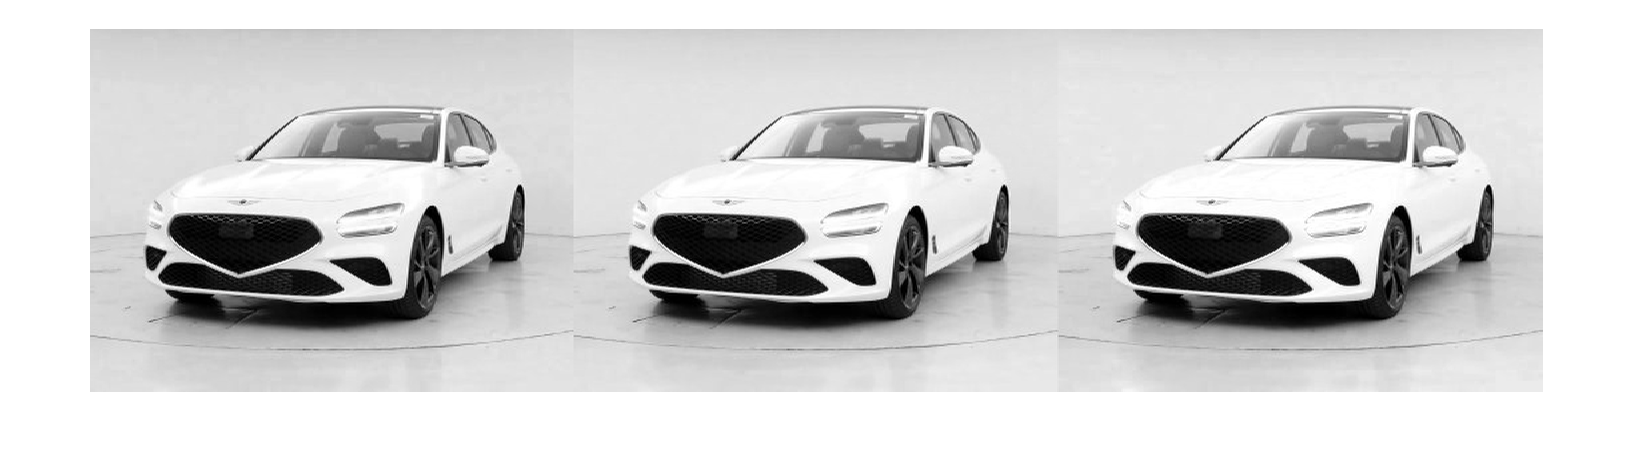

figure(5);
imshow(uint8(new_img))